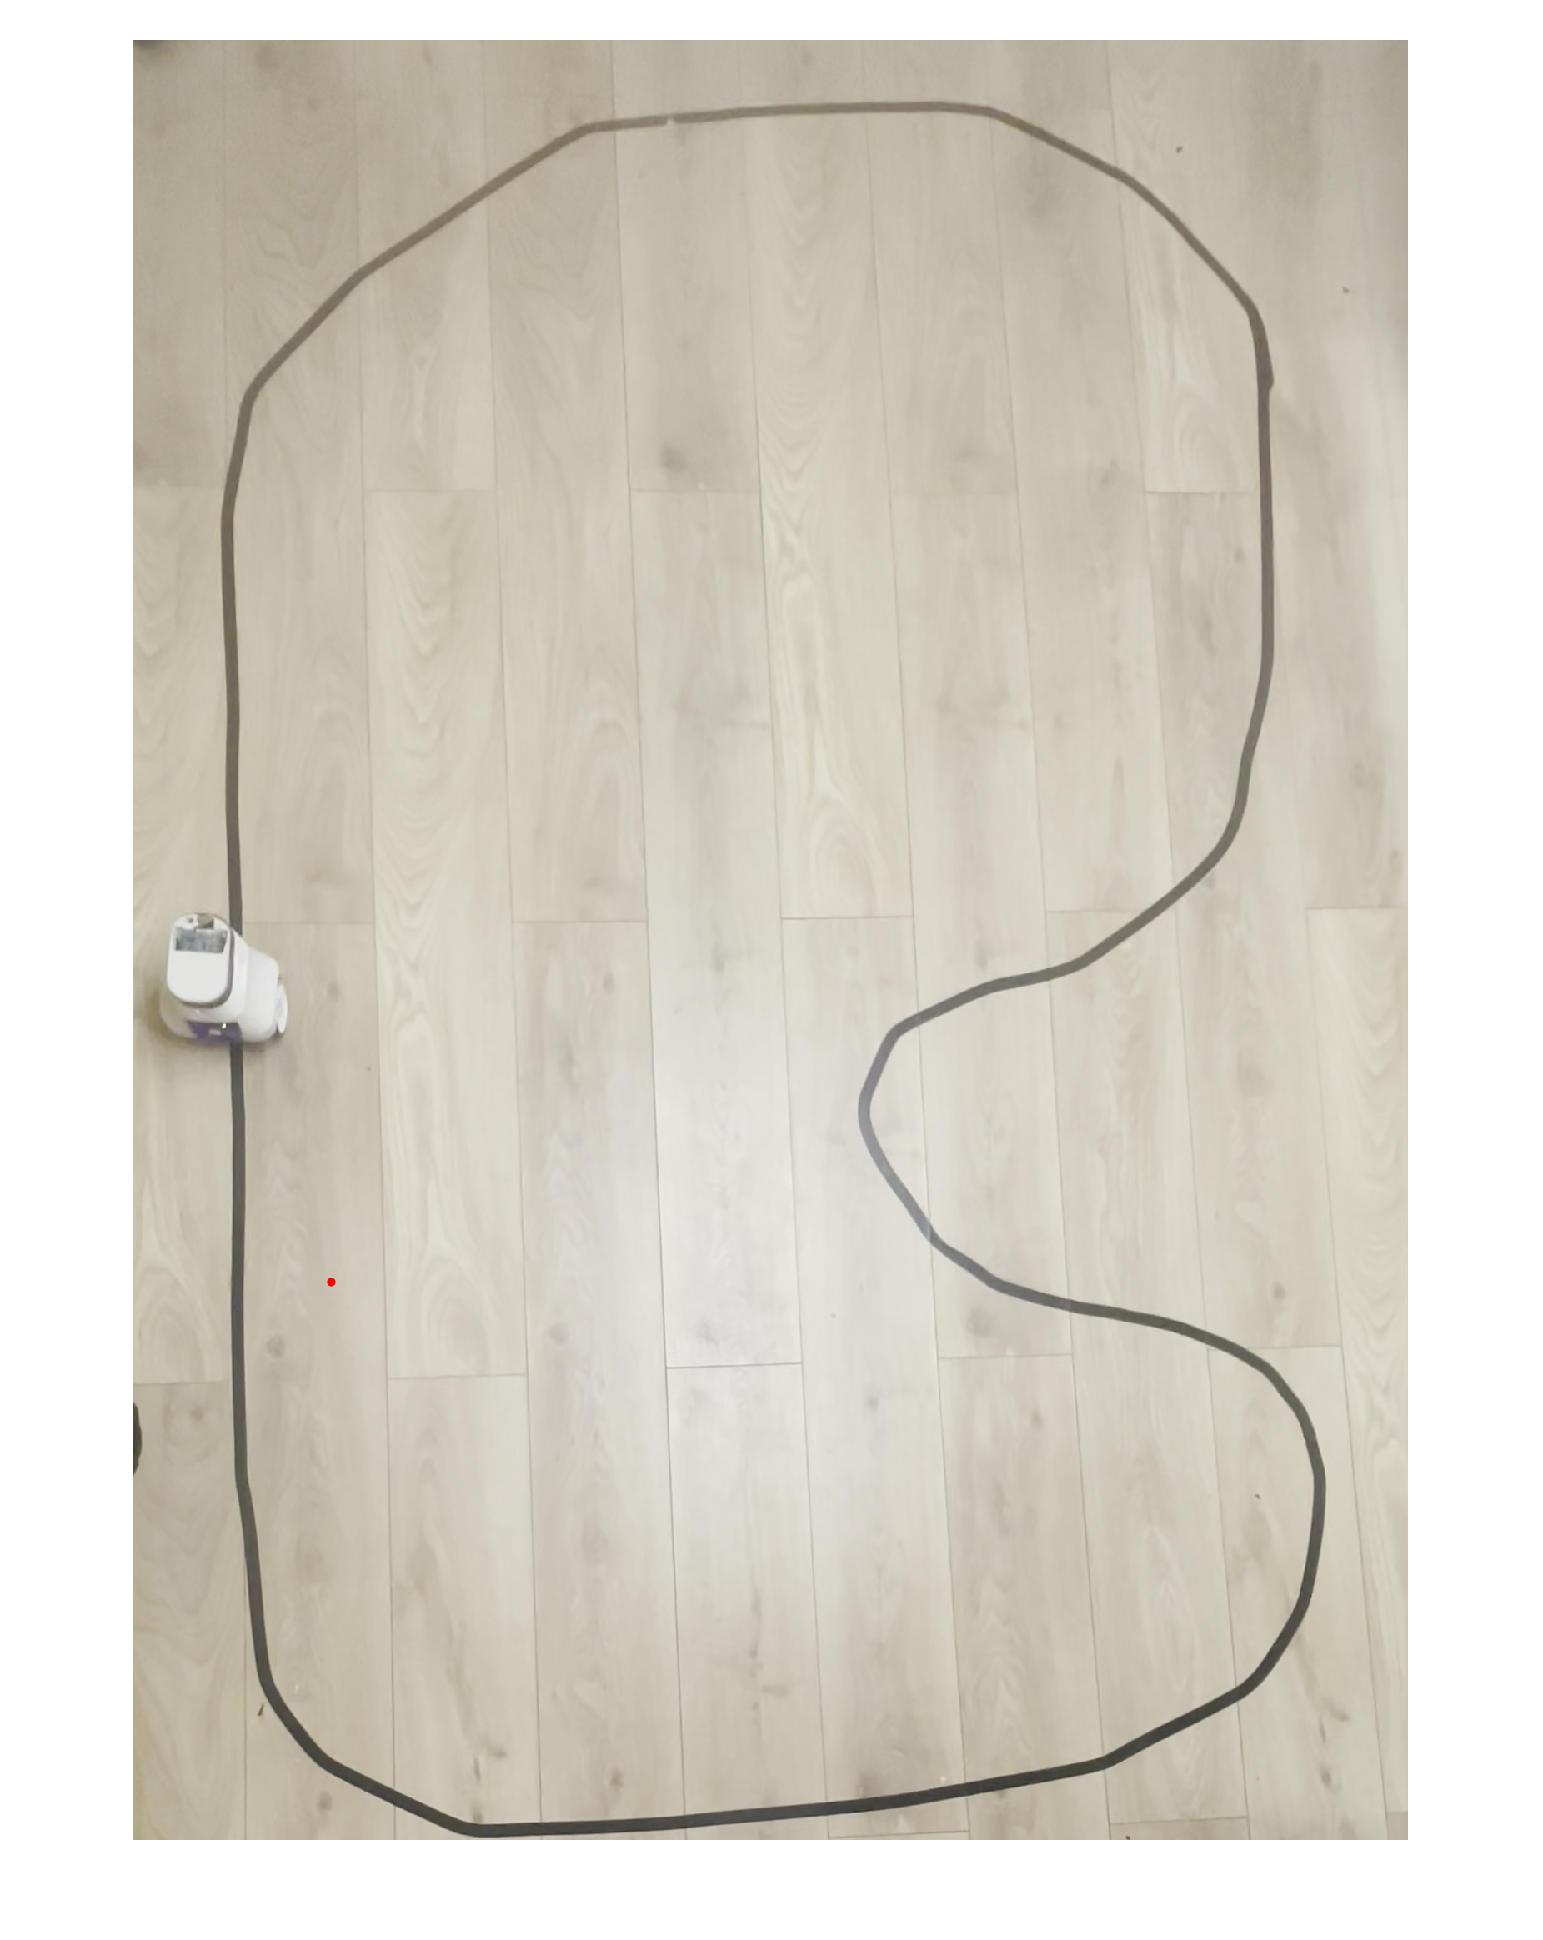

clc; clear; close all;

%% Load Video
video = VideoReader('DataSets/IMG_9851.MOV');
outputVideo = VideoWriter('tracked_robot.avi'); % Output video
outputVideo.FrameRate = video.FrameRate;
open(outputVideo);

%% Background Subtraction for Robot Detection
foregroundDetector = vision.ForegroundDetector('NumGaussians', 3, 'NumTrainingFrames', 50);

% Tracking variables
robot_positions = [];
track_positions = [];

%% Process Video Frames
while hasFrame(video)
    frame = readFrame(video);
    grayFrame = rgb2gray(frame);

    % Extract Black Track
    trackMask = extractTrack(grayFrame);
    [trackContour, trackCenterline] = getTrackCenter(trackMask);

    % Detect Moving Robot
    foreground = step(foregroundDetector, frame); % Detect motion
    robotPosition = detectWhiteRobot(foreground);

    % Store positions
    if ~isempty(robotPosition)
        robot_positions = [robot_positions; robotPosition];
        frame = insertShape(frame, 'FilledCircle', [robotPosition, 5], 'Color', 'red', 'Opacity', 1);
    end
    if ~isempty(trackCenterline)
        track_positions = [track_positions; trackCenterline];
        frame = insertShape(frame, 'FilledCircle', [trackCenterline, 3], 'Color', 'blue', 'Opacity', 1);
    end

    % Show frame
    imshow(frame);
    drawnow;

    % Save frame to output video
    writeVideo(outputVideo, frame);
end

close(outputVideo);
fprintf('Tracked video saved as tracked_robot.avi\n');

%% Compute Tracking Performance
if ~isempty(robot_positions) && ~isempty(trackContour)
    computeTrackingError(robot_positions, trackContour);
end

%% Plot Performance
figure;
hold on;
plot(track_positions(:,1), track_positions(:,2), 'b-', 'LineWidth', 2); % Track path
plot(robot_positions(:,1), robot_positions(:,2), 'r-', 'LineWidth', 2); % Robot path
scatter(robot_positions(:,1), robot_positions(:,2), 5, 'r', 'filled');
legend('Track', 'Robot Path');
xlabel('X Position');
ylabel('Y Position');
title('Robot Tracking Performance');
hold off;

%% --- Function Definitions ---
% Extract Track from Image
function trackMask = extractTrack(grayFrame)
    trackMask = grayFrame < 50; % Threshold for black regions
    trackMask = imopen(trackMask, strel('disk', 5)); % Remove noise
end

% Find Track Centerline
function [trackContour, trackCenterline] = getTrackCenter(trackMask)
    stats = regionprops(trackMask, 'Centroid', 'Area', 'PixelList');
    if isempty(stats)
        trackContour = [];
        trackCenterline = [];
        return;
    end
    [~, maxIdx] = max([stats.Area]); % Largest object (track)
    trackCenterline = round(stats(maxIdx).Centroid);
    trackContour = stats(maxIdx).PixelList;
end

%  Detect White Robot Using Motion (Background Subtraction)
function robotPosition = detectWhiteRobot(foreground)
    stats = regionprops(foreground, 'Centroid', 'Area');
    if isempty(stats)
        robotPosition = [];
        return;
    end
    [~, maxIdx] = max([stats.Area]); % Largest moving object = robot
    robotPosition = round(stats(maxIdx).Centroid);
end

% Compute Tracking Error
function computeTrackingError(robot_positions, trackContour)
    errors = [];
    for i = 1:length(robot_positions)
        pos = robot_positions(i,:);
        distances = sqrt((trackContour(:,1) - pos(1)).^2 + (trackContour(:,2) - pos(2)).^2);
        errors = [errors; min(distances)];
    end
    avgError = mean(errors);
    fprintf('Average Tracking Error: %.2f pixels\n', avgError);
end
